pretrainedNetwork = fullfile('D:\semanticSegmentation\deeplabv3plusResnet18CamVid\deeplabv3plusResnet18CamVid.mat');  
data = load(pretrainedNetwork);
net = data.net;
classes = string(net.Layers(end).Classes)

classes = 11×1 string array
    "Sky"
    "Building"
    "Pole"
    "Road"
    "Pavement"
    "Tree"
    "SignSymbol"
    "Fence"
    "Car"
    "Pedestrian"
    "Bicyclist"


I = imread('highway.png');

inputSize = net.Layers(1).InputSize;
I = imresize(I,inputSize(1:2));

C = semanticseg(I,net);

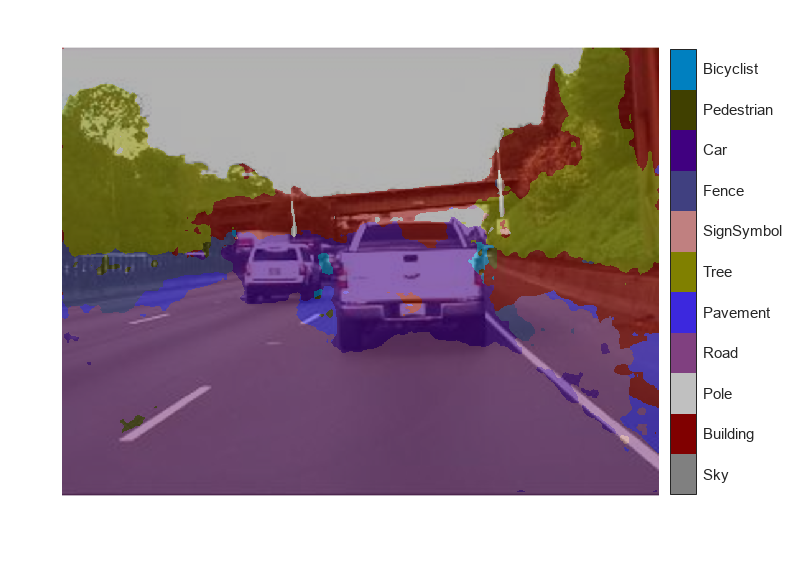

cmap = camvidColorMap;
B = labeloverlay(I,C,'Colormap',cmap,'Transparency',0.4);
figure
imshow(B)
pixelLabelColorbar(cmap, classes);

function data = augmentImageAndLabel(data, xTrans, yTrans)
% Augment images and pixel label images using random reflection and
% translation.

for i = 1:size(data,1)
    
    tform = randomAffine2d(...
        'XReflection',true,...
        'XTranslation', xTrans, ...
        'YTranslation', yTrans);
    
    % Center the view at the center of image in the output space while
    % allowing translation to move the output image out of view.
    rout = affineOutputView(size(data{i,1}), tform, 'BoundsStyle', 'centerOutput');
    
    % Warp the image and pixel labels using the same transform.
    data{i,1} = imwarp(data{i,1}, tform, 'OutputView', rout);
    data{i,2} = imwarp(data{i,2}, tform, 'OutputView', rout);
    
end
end
function [imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionCamVidData(imds,pxds)
% Partition CamVid data by randomly selecting 60% of the data for training. The
% rest is used for testing.
    
% Set initial random state for example reproducibility.
rng(0); 
numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% Use 60% of the images for training.
numTrain = round(0.60 * numFiles);
trainingIdx = shuffledIndices(1:numTrain);

% Use 20% of the images for validation
numVal = round(0.20 * numFiles);
valIdx = shuffledIndices(numTrain+1:numTrain+numVal);

% Use the rest for testing.
testIdx = shuffledIndices(numTrain+numVal+1:end);

% Create image datastores for training and test.
trainingImages = imds.Files(trainingIdx);
valImages = imds.Files(valIdx);
testImages = imds.Files(testIdx);

imdsTrain = imageDatastore(trainingImages);
imdsVal = imageDatastore(valImages);
imdsTest = imageDatastore(testImages);

% Extract class and label IDs info.
classes = pxds.ClassNames;
labelIDs = camvidPixelLabelIDs();

% Create pixel label datastores for training and test.
trainingLabels = pxds.Files(trainingIdx);
valLabels = pxds.Files(valIdx);
testLabels = pxds.Files(testIdx);

pxdsTrain = pixelLabelDatastore(trainingLabels, classes, labelIDs);
pxdsVal = pixelLabelDatastore(valLabels, classes, labelIDs);
pxdsTest = pixelLabelDatastore(testLabels, classes, labelIDs);
end
function cmap = camvidColorMap()
% Define the colormap used by CamVid dataset.

cmap = [
    128 128 128   % Sky
    128 0 0       % Building
    192 192 192   % Pole
    128 64 128    % Road
    60 40 222     % Pavement
    128 128 0     % Tree
    192 128 128   % SignSymbol
    64 64 128     % Fence
    64 0 128      % Car
    64 64 0       % Pedestrian
    0 128 192     % Bicyclist
    ];

% Normalize between [0 1].
cmap = cmap ./ 255;
end
function pixelLabelColorbar(cmap, classNames)
% Add a colorbar to the current axis. The colorbar is formatted
% to display the class names with the color.

colormap(gca,cmap)

% Add colorbar to current figure.
c = colorbar('peer', gca);

% Use class names for tick marks.
c.TickLabels = classNames;
numClasses = size(cmap,1);

% Center tick labels.
c.Ticks = 1/(numClasses*2):1/numClasses:1;

% Remove tick mark.
c.TickLength = 0;
end
function labelIDs = camvidPixelLabelIDs()
% Return the label IDs corresponding to each class.
%
% The CamVid dataset has 32 classes. Group them into 11 classes following
% the original SegNet training methodology [1].
%
% The 11 classes are:
%   "Sky" "Building", "Pole", "Road", "Pavement", "Tree", "SignSymbol",
%   "Fence", "Car", "Pedestrian",  and "Bicyclist".
%
% CamVid pixel label IDs are provided as RGB color values. Group them into
% 11 classes and return them as a cell array of M-by-3 matrices. The
% original CamVid class names are listed alongside each RGB value. Note
% that the Other/Void class are excluded below.
labelIDs = { ...
    
    % "Sky"
    [
    128 128 128; ... % "Sky"
    ]
    
    % "Building" 
    [
    000 128 064; ... % "Bridge"
    128 000 000; ... % "Building"
    064 192 000; ... % "Wall"
    064 000 064; ... % "Tunnel"
    192 000 128; ... % "Archway"
    ]
    
    % "Pole"
    [
    192 192 128; ... % "Column_Pole"
    000 000 064; ... % "TrafficCone"
    ]
    
    % Road
    [
    128 064 128; ... % "Road"
    128 000 192; ... % "LaneMkgsDriv"
    192 000 064; ... % "LaneMkgsNonDriv"
    ]
    
    % "Pavement"
    [
    000 000 192; ... % "Sidewalk" 
    064 192 128; ... % "ParkingBlock"
    128 128 192; ... % "RoadShoulder"
    ]
        
    % "Tree"
    [
    128 128 000; ... % "Tree"
    192 192 000; ... % "VegetationMisc"
    ]
    
    % "SignSymbol"
    [
    192 128 128; ... % "SignSymbol"
    128 128 064; ... % "Misc_Text"
    000 064 064; ... % "TrafficLight"
    ]
    
    % "Fence"
    [
    064 064 128; ... % "Fence"
    ]
    
    % "Car"
    [
    064 000 128; ... % "Car"
    064 128 192; ... % "SUVPickupTruck"
    192 128 192; ... % "Truck_Bus"
    192 064 128; ... % "Train"
    128 064 064; ... % "OtherMoving"
    ]
    
    % "Pedestrian"
    [
    064 064 000; ... % "Pedestrian"
    192 128 064; ... % "Child"
    064 000 192; ... % "CartLuggagePram"
    064 128 064; ... % "Animal"
    ]
    
    % "Bicyclist"
    [
    000 128 192; ... % "Bicyclist"
    192 000 192; ... % "MotorcycleScooter"
    ]
    
    };
end